**Queston 1**

clc;
clear all;
close all;
% 1c

%1d

N = [100, 1000]';
error_norm = zeros(length(N),1);
for n = 1:length(N)
    a = 1:1:N(n);
    b = -1/3 .*((1:1:N(n)-1) + 1);
    c = b;
    d = -1/6 .*((1:1:N(n)-2) +2);
    e = d;
    f = zeros(N(n) -4,1);
    f = vertcat([1/2, 1/6]',f);    
    f(end+1) = 1/6;
    f(end+1) = 1/2;
    x_f =fast_pentadiag(a,b,c,d,e,f);
    A = diag(d,-2)+diag(b,-1)+diag(a)+diag(c,1)+diag(e,2);
    x_ge = A\f;
    error = abs(x_ge - x_f);
    error_norm(n) = norm(error,2);
end

T= table(N,error_norm,'VariableNames',{'N', 'Error norm'})

T = 2×2 table
     N      Error norm
    ____    __________

     100    1.2218e-13
    1000    1.3501e-12


**Queston 2**

%2a

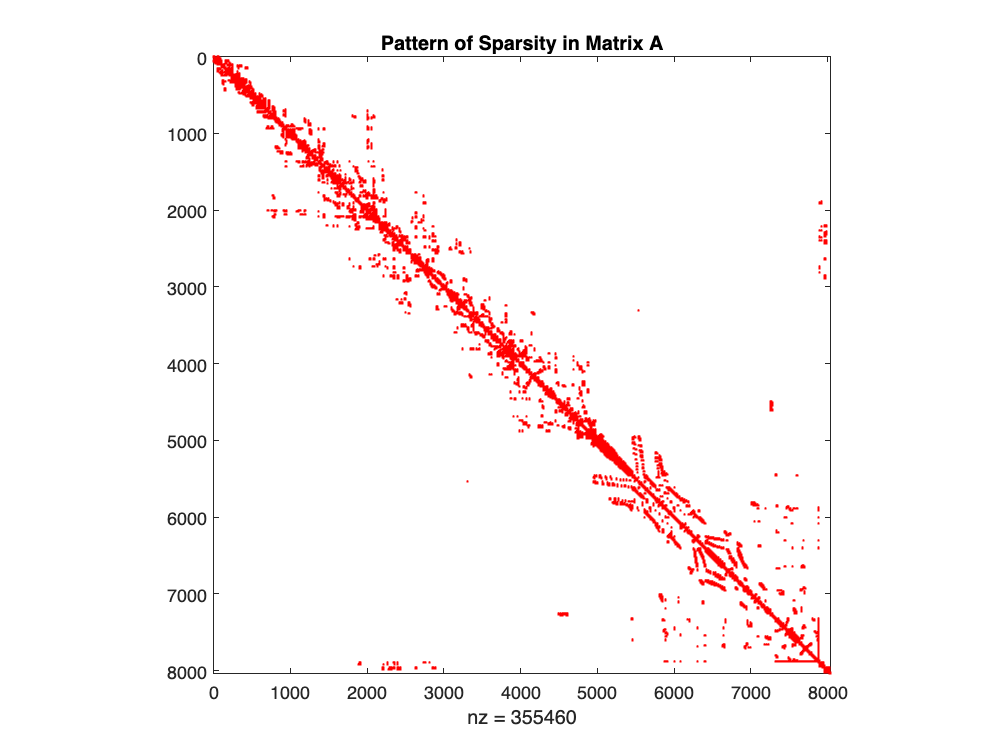

load bcsstk38;
A = Problem.A;
spy(A,'r')
title("Pattern of Sparsity in Matrix A")

sparsity_ratio = 1 - (nnz(A)/numel(A))

sparsity_ratio = 0.9945

%2b

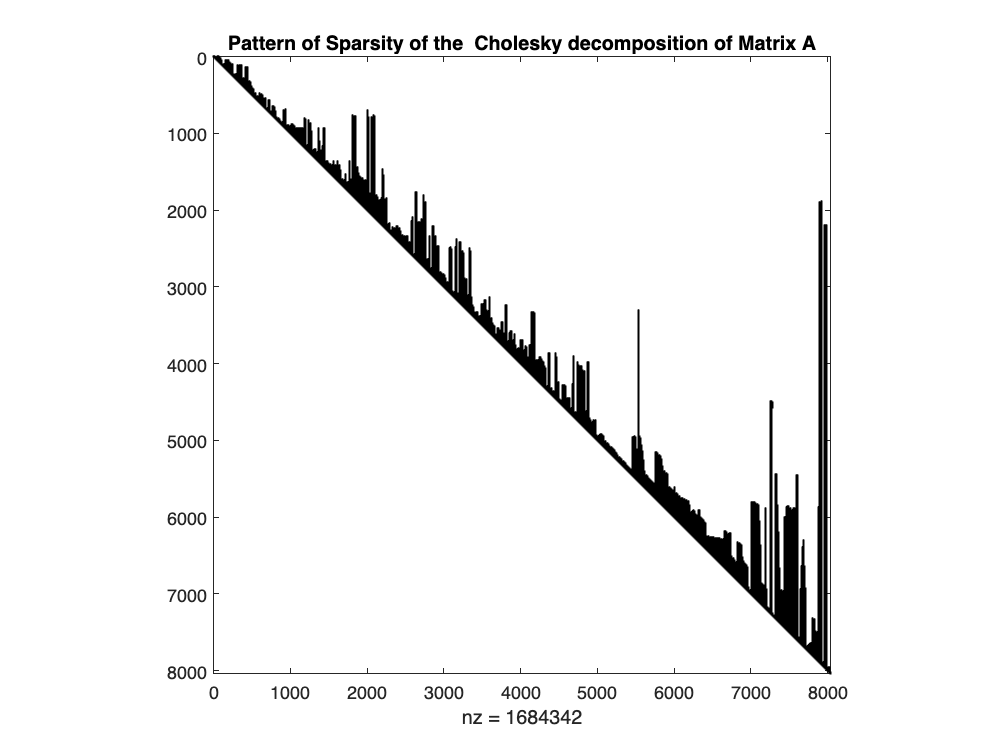

% Compute the Cholesky factorization of the matrix
R = chol(A);
spy(R,'k')
title("Pattern of Sparsity of the  Cholesky decomposition of Matrix A")

num_fillin = nnz(R)/nnz(A)

num_fillin = 4.7385

%2c

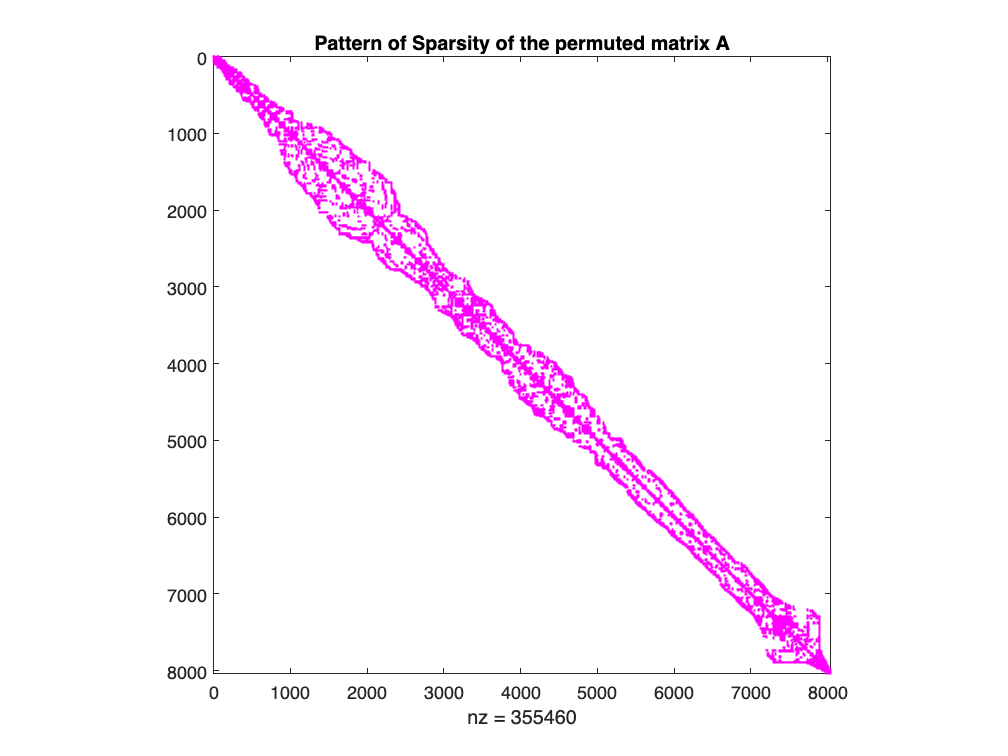

% Reorder the matrix using symrcm
p = symrcm(A);
B = A(p,p);

% Compute the Cholesky factorization of the reordered matrix
L = chol(B);


spy(B,'m')
title("Pattern of Sparsity of the permuted matrix A")

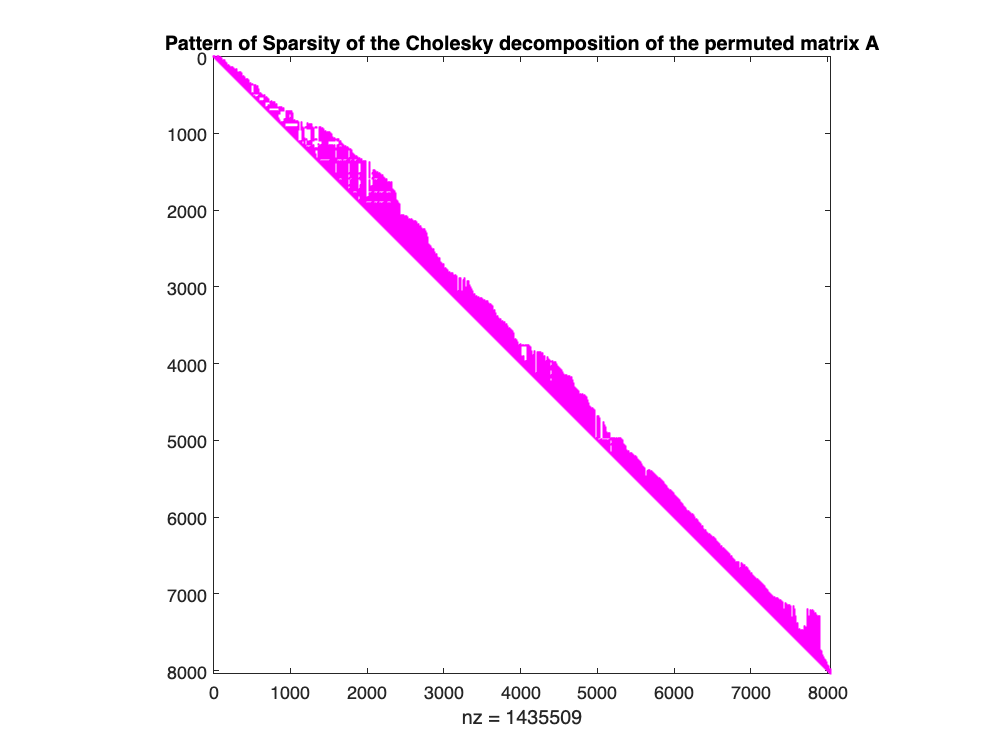

spy(L,'m')
title("Pattern of Sparsity of the Cholesky decomposition of the permuted matrix A")

num_fillin2  = nnz(L)/nnz(B)

num_fillin2 = 4.0385

**Queston 3**

%3c


n = 100;
beta = 0;

h = 1/(n+1);
a1 =-2* ones(n,1);
a2 = ones(n-1,1);

A = diag(a2,-1)+diag(a1)+diag(a2,1);
A = sparse(A);

u = zeros(n,1); 
u(1) = 1;

v = 2*ones(1,n);
b = zeros(n,1);

gamma = 2/3;
b =-2* h^2 *(ones(n-2,1))';
b= [-2*h^2  - 2*gamma / h, b];

b= [b, -2*h^2 - beta]';

x = fast_algorithm(u,v,b,A)

x =     0.9999
    0.9996
    0.9991
    0.9985
    0.9976
    0.9965
    0.9952
    0.9938
    0.9921
    0.9902


px =1- (h.*(1:1:n)').^2

px =     0.9999
    0.9996
    0.9991
    0.9984
    0.9975
    0.9965
    0.9952
    0.9937
    0.9921
    0.9902


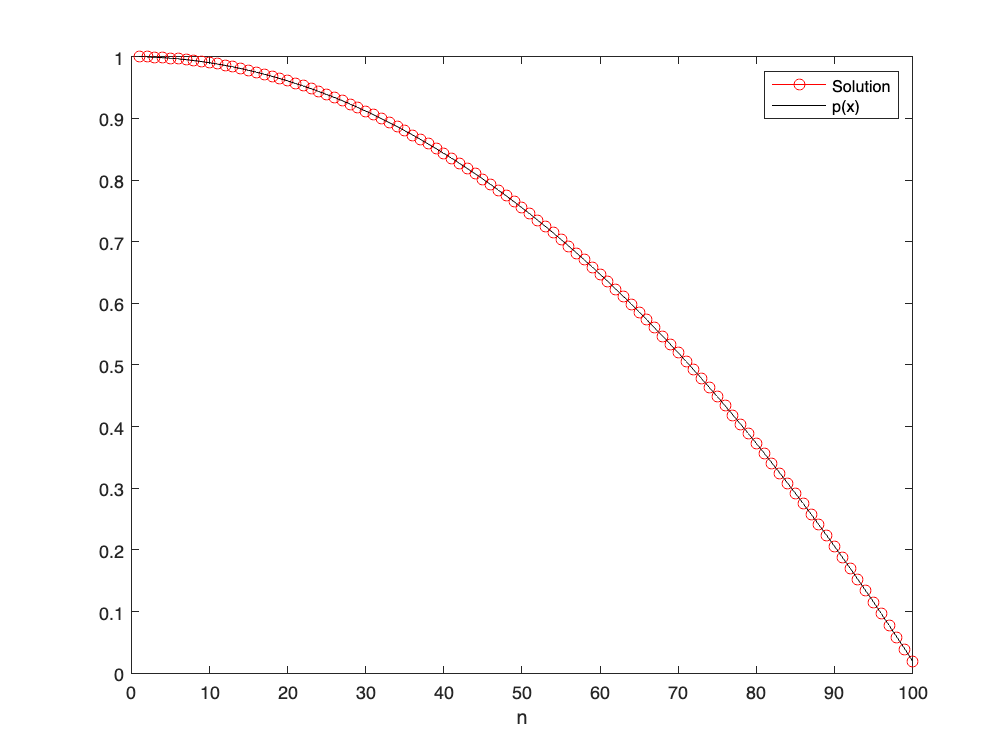


plot(x,'r-o','DisplayName','Solution'), hold on
plot(px,'k','DisplayName','p(x)')
xlabel('n')
legend();

**Queston 5**

A = [3 -1 -1 0 0;
    -1 4 -1 -1 0;
    -1 -1 5 -1 -1;
    0 -1 -1 4 -1;
    0 0 -1 -1 3];
b = [3 -5 5 -5 3]';

% 5a
[iter] = iterative_method(A,b,1e-6,'jacobi')

iter = 34

%5b
[iter] = iterative_method(A,b,1e-6,'gauss_seidel')

iter = 18

function x = fast_pentadiag(a,b,c,d,e,f)
% STEP 1
n = length(f);
x = zeros(n,1);
B = zeros(n-2,1);
K = zeros(n-2,1);
for i = 1:n-2
    B(i) = b(i)/a(i);
    K(i) = d(i)/a(i);
    a(i+1) = a(i+1) - B(i)*c(i);
    c(i+1) = c(i+1) - B(i)*e(i);
    b(i+1) = b(i+1) - K(i)*c(i);
    a(i+2) = a(i+2) - K(i)*e(i);
    f(i+1) = f(i+1) - B(i)*f(i);
    f(i+2) = f(i+2) - K(i)*f(i);
end
a(n) = a(n) - (b(n - 1)/a(n - 1))*c(n-1);
f(n) = f(n) - (b(n - 1)/a(n - 1))*f(n - 1);
x(n) = f(n)/a(n);
x(n - 1) = (f(n - 1) - x(n)*c(n - 1))/a(n - 1);
%STEP 2
for i = n-2:-1:1
    x(i) = (f(i) - x(i+1)*c(i) - x(i+2)*e(i))/a(i);
end
end

function [iter] = iterative_method(A,b,tol,method)
x_init = zeros(length(b),1);
iter = 0;
switch method
    
    case 'jacobi'
        D = diag(diag(A));
        while (true)
            zk = D\(b - A*x_init);
            x = x_init+ zk;
            
            
            if norm(b - A*x,2)< tol*norm(b,2)
                break;
            end
            x_init = x;
            iter = iter + 1;
        end

    case 'gauss_seidel'

        n = length(b);
        x =zeros(length(b),1);

        while (true)
              for i = 1:n
                x(i) = (b(i) - A(i,1:i-1) * x(1:i-1) - A(i,i+1:n) * x_init(i+1:n)) / A(i,i);
              end
            if norm(b - A*x,2)< tol*norm(b,2) 
                break;
            end
            x_init = x;
            iter = iter + 1;
            
        end
end
end

function x = fast_algorithm(u,v,b,A)

        p1 = A\b;

        p2 = A\u;

        alpha = 1 - v*p2;

        x = p1 + (1/alpha).*p2*v*p1;
end